%BPSK Simulation
%Practical and Theoretical Bit Error Rate (BER) Comparison in AWGN Channel

%Setting up number of bits in Message Signal
nBits = 1000;

%SNR array for experiment
SNRdB = 0:1:10;

%Calculating theoretical BER values from Q-function using SNR array
ThBER = 0.5*erfc(sqrt(10.^(SNRdB/10)));

%Setting up number of iterations of experiments for a single SNR value
nIter = 1000;

%Calculating simulated BER values using BPSK Simulator function
SimBER = BPSKsimulator(SNRdB, nBits, nIter);

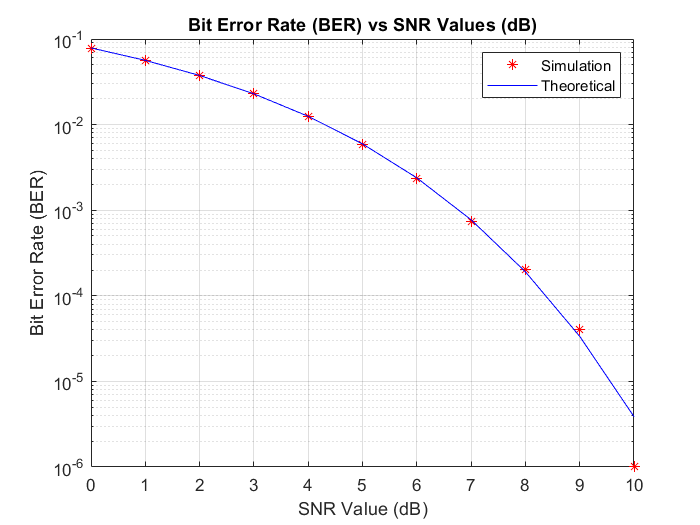

%Plotting results of theoretical and simulated experiments
figure(1);

%Simulated Experiments
semilogy(SNRdB, SimBER, '*r');
hold on;

%Theoretical BER using Q-function
semilogy(SNRdB, ThBER, 'b');
grid on;

%Axes and Plot labels
legend('Simulation', 'Theoretical');
xlabel('SNR Value (dB)');
ylabel('Bit Error Rate (BER)');
title('Bit Error Rate (BER) vs SNR Values (dB)');